## Glucose absorption model (GAM)

### 1. Load data from the CGM

addpath('CGM_data/')
[t, g] = importCGM('Dat_D01_sensor.csv');       % g - [mmol/L]
[t_G, G] = importCGM('Dat_D01_CalBG.csv');      % G - [mmol/L]
[t_i_B, i_B] = importCGM('Dat_D01_bolus.csv');  % i_B - [U]
[t_i_b, i_b] = importCGM('Dat_D01_Basal.csv');  % i_b - [µIU/mL]
[t_d, d] = importCGM('Dat_D01_carb.csv');       % d - [g]

Given

t_start = t(1);          % [min]
t_end = t(end);          % [min]

Ts = 5;                  % [min]
BW = 64.4;               % [kg|

### Preprocessing

**TODO (not working yet):** Change interval (**Optional**)

t_start = 500;          % [min]
t_end = 1200;           % [min]

[t, g] = setPeriod(t, g , t_start, t_end);
[t_G, G] = setPeriod(t_G, G , t_start, t_end);
[t_i_B, i_B] = setPeriod(t_i_B, i_B , t_start, t_end);
[t_i_b, i_b] = setPeriod(t_i_b, i_b , t_start, t_end);
[t_d, d] = setPeriod(t_d, d , t_start, t_end);

t_diff = t_end-t_start;
t_span = t_start:t_end;  % [min]

[~,idx] = unique(t_i_b, 'last');
t_i_b = t_i_b(idx);
i_b = i_b(idx);

v = interp1(t_i_b, i_b, t_span)';
for i = 0:Ts-1
    v(t_i_B+i) = v(t_i_B+i) + i_B*10; 
end
v = v*10^5/BW/Ts;

d_all = zeros(t_diff+1,1);
for i = 0:Ts-1
    d_all(t_d+i) = d;
end
d_all = d_all*10^4/BW/Ts;

### 2. Plot data from the CGM

Glycemia

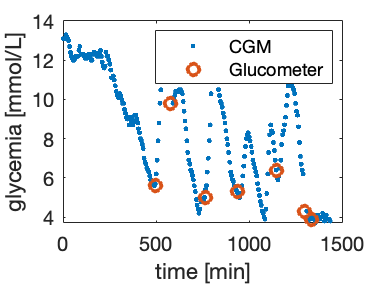

clf(figure(1)); figure(1)
plot(t, g, '.','Linewidth',2); hold on
plot(t_G, G, 'o','Linewidth',2)
xlabel('time [min]'); ylabel('glycemia [mmol/L]')
legend('CGM', 'Glucometer')

Carbohydrate uptake

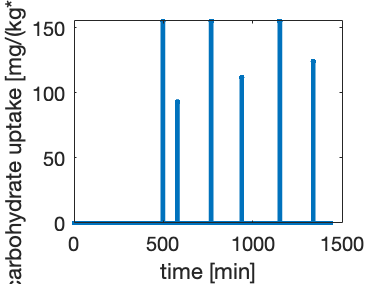

clf(figure(2)); figure(2)
stem(t_span, d_all, '.','Linewidth',2)
xlabel('time [min]'); ylabel('carbohydrate uptake [mg/(kg*min)]')

Insulin

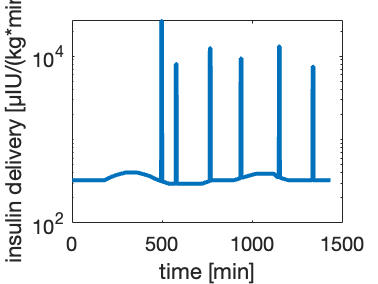

clf(figure(3)); figure(3)
semilogy(t_span, v,'Linewidth',2); hold on
%plot(t_i_b, i_b, '.','Linewidth',2); hold on
%stem(t_i_B, i_B, '.','Linewidth',2)
xlabel('time [min]'); ylabel('insulin delivery [µIU/(kg*min)]')

### Validation variables

t_start = 400;          % [min]
t_end = 1400;           % [min]
idx_t_sim = find(t >= t_start & t <= t_end);
t_sim = t(idx_t_sim);

IAM

Ti = 44.55;       % [min]
ki = 0.1645;        % [1/min]
Vi = 138.8;         % [mL/kg]
S10 = Ti*v(find(t >= t_start, 1, 'first'));                % [µIU/kg]
S20 = S10;                  % [µIU/kg] 
I0 = 1/(ki*Vi*Ti)*S20;      % [µIU/mL]

BMM

Ib = 1/(ki*Vi*Ti)*S20;       % [µIU/mL]
Gb = g(find(t >= t_start, 1, 'first'));% [mmol/L]
G0 = Gb;          % [mmol/L]
X0 = 0;            % [1/min]
p2 = 0.0106;       % [1/min]
Si = 0.00159;       % [mL/(µIU*min)]
Vg = 1.467*18;        % [dL/kg] Volume of distribution glucose
%Vg = Vg / 180 % [kg/dL mg/kg/min] -> [kg/L mmol/kg/min]

GAM

Sg = 0.032;         % [1/min]
TD = 33.474;        % [1/min]
D0 = 0;             % [mg/kg*min]
Ra0 = 0;            % [mg/kg*min]

A_G = 0.95;         % []

### 3. Compile a simulation scheme of GAM

open_system('full_sim.slx')

Set SIMULINK initials

d_sim.time = t_span;
d_sim.signals.values = d_all;
d_sim.signals.dimensions = 1;

g_sim.time = t;
g_sim.signals.values = g;
g_sim.signals.dimensions = 1;

v_sim.time = t_span;
v_sim.signals.values = v;
v_sim.signals.dimensions = 1;

set_param('full_sim','StartTime',num2str(t_start),'StopTime',num2str(t_end))

set_param('full_sim/BMM/Gain_Sg', 'Gain', num2str(Sg));
set_param('full_sim/GAM/T_D', 'Value', num2str(TD));
set_param('full_sim/GAM/Integrator_D', 'InitialCondition', num2str(D0));
set_param('full_sim/GAM/Integrator_Ra', 'InitialCondition', num2str(Ra0));

out0 = sim('full_sim.slx');

### Initialize variables for other subsystems

%t_start = 500;          % [min]
%t_end = 1200;           % [min]
%idx_t_sim = find(t >= t_start & t <= t_end);
%t_sim = t(idx_t_sim);

IAM

Ti = 43.8971;       % [min]
ki = 0.1356;        % [1/min]
Vi = 167.6;         % [mL/kg]
S10 = Ti*v(find(t >= t_start, 1, 'first'));                % [µIU/kg]
S20 = S10;                  % [µIU/kg] 
I0 = 1/(ki*Vi*Ti)*S20;      % [µIU/mL]

BMM

Ib = 1/(ki*Vi*Ti)*S20;       % [µIU/mL]
Gb = g(find(t >= t_start, 1, 'first'));          % [mmol/L]
G0 = Gb;          % [mmol/L]
X0 = 0;            % [1/min]
p2 = 0.01084;       % [1/min]
Si = 0.001595;       % [mL/(µIU*min)]
Vg = 1.467*18;        % [dL/kg] Volume of distribution glucose
%Vg = Vg / 180 % [kg/dL mg/kg/min] -> [kg/L mmol/kg/min]

GAM

Sg = 0.032;         % [1/min]
TD = 33.474;        % [1/min]
D0 = 0;             % [mg/kg*min]
Ra0 = 0;            % [mg/kg*min]

A_G = 0.95;         % []

### 4. Identification

Set optimization options

set_param('full_sim','StartTime',num2str(t_start),'StopTime',num2str(t_end))

theta0 = [Sg TD]

theta0 =     0.0320   33.4740


opts = optimset('Display', 'iter', 'MaxIter', 250);

Run identification

 
 Iteration   Func-count     min f(x)         Procedure
     0            1          793.046         
     1            3          778.715         initial simplex
     2            5          768.632         expand
     3            7          761.208         expand
     4            9            760.8         reflect
     5           11          760.442         contract inside
     6           13          758.686         reflect
     7           15          758.686         contract inside
     8           17          758.686         contract inside
     9           19           758.61         contract inside
    10           21           758.61         contract inside
    11           23          758.569         contract inside
    12           24          758.569         reflect
    13           26          758.567         contract inside
    14           28          758.565         contract inside
    15           30          758.555         contract inside
    16           32     

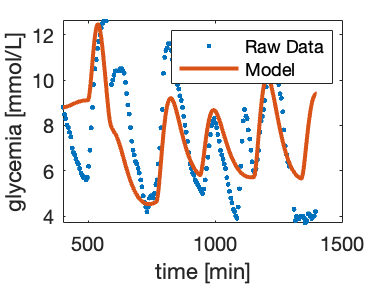

    41           77          758.554         contract inside
 
Optimization terminated:
 the current x satisfies the termination criteria using OPTIONS.TolX of 1.000000e-04 
 and F(X) satisfies the convergence criteria using OPTIONS.TolFun of 1.000000e-04 



x_opt =     0.0247   38.9287


fval = 758.5544

exitflag = 1

output = struct with fields:
    iterations: 41
     funcCount: 77
     algorithm: 'Nelder-Mead simplex direct search'
       message: 'Optimization terminated:↵ the current x satisfies the termination criteria using OPTIONS.TolX of 1.000000e-04 ↵ and F(X) satisfies the convergence criteria using OPTIONS.TolFun of 1.000000e-04 ↵'


[x_opt, fval, exitflag, output] = ...
    fminsearch(@objFcn_CGM, theta0, opts, t_sim, 1)


Sg_opt = x_opt(1);
TD_opt = x_opt(2);

Plot simulation output **Glucose Supply Rate**

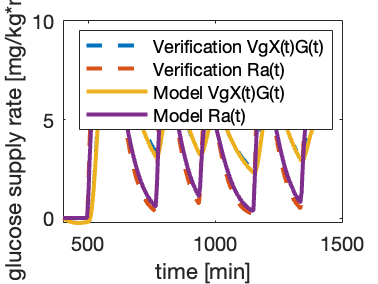

out = sim('full_sim.slx');
ra_BMM = interp1(out0.Ra_est(:,1),out0.Ra_est(:,2), t);
ra_GAM = interp1(out0.Ra_est(:,1),out0.Ra_est(:,3), t);
clf(figure(3)); figure(3)
plot(t, [ra_BMM ra_GAM], '--','Linewidth',2); hold on

ra_BMM = interp1(out.Ra_est(:,1),out.Ra_est(:,2), t);
ra_GAM = interp1(out.Ra_est(:,1),out.Ra_est(:,3), t);
plot(t, [ra_BMM ra_GAM],'Linewidth',2);
xlabel('time [min]'); ylabel('glucose supply rate [mg/kg*mol]')
legend('Verification VgX(t)G(t)', 'Verification Ra(t)', ...
       'Model VgX(t)G(t)', 'Model Ra(t)')

Plot simulation output **Glycemia**

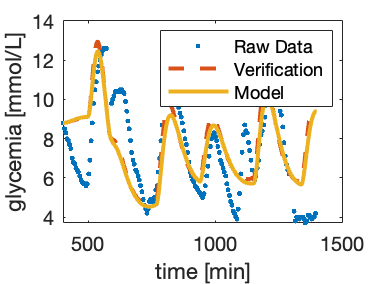

clf(figure(4)); figure(4)
plot(t_sim, g(idx_t_sim), '.', 'Linewidth', 2); hold on
plot(out0.G_est(:,1), out0.G_est(:,3), '--','Linewidth',2)
plot(out.G_est(:,1), out.G_est(:,3), 'Linewidth',2)
xlabel('time [min]'); ylabel('glycemia [mmol/L]')
legend('Raw Data', 'Verification', 'Model');

g_est = interp1(out.G_est(:,1),out.G_est(:,3), t_sim);
g_sim = g(idx_t_sim);

g_sim =     8.8000
    8.5000
    8.3000
    8.0000
    7.9000
    7.7000
    7.5000
    7.0000
    6.8000
    6.7000


VAF = ( 1 - var(g_sim-g_est)/var(g_sim) )*100

VAF = 31.2624

RMSE = sqrt( ((g_sim-g_est)'*(g_sim-g_est)) / length(g_sim))

RMSE = 1.9774

SFM = (1 - sqrt((g_sim-g_est)'*(g_sim-g_est)) / ...
       sqrt((g_sim-mean(g_sim))'*(g_sim-mean(g_sim))))*100

SFM = 16.9949